# Deep learning for classification on the MNIST dataset

Copyright 2018 The MathWorks, Inc.

## Prepare the dataset

In this example, we will perform image classification using deep learning (from scratch) on the MNIST dataset. The MNIST dataset is a set of handwritten digits categorized 0-9 and is available at [http://yann.lecun.com/exdb/mnist/.](http://yann.lecun.com/exdb/mnist/.)

The following line will download (if necessary) and prepare the dataset to use in MATLAB.

% [imgDataTrain, labelsTrain, imgDataTest, labelsTest] = prepareData;

Preparing MNIST data...
MNIST data preparation complete.


## Let's look at a few of the images

We will pick a random sampling of the images to take a closer look.

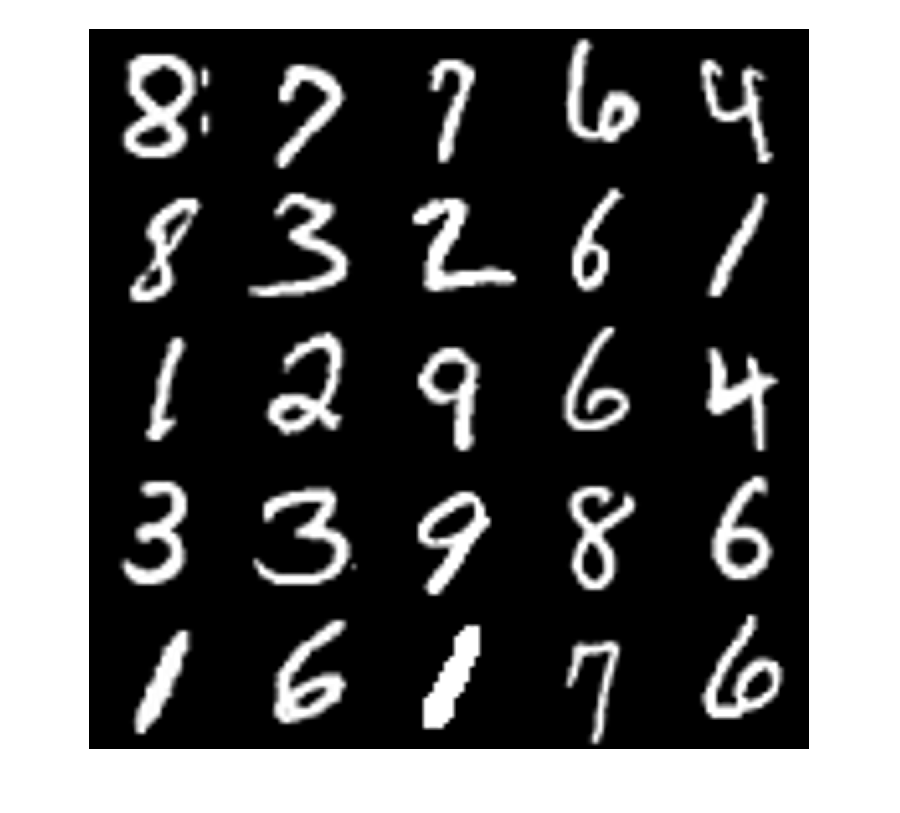

% warning off images:imshow:magnificationMustBeFitForDockedFigure
% perm = randperm(numel(labelsTrain), 25);
% subset = imgDataTrain(:,:,1,perm);
% montage(subset)

## How do we classify a digit?

We'll start with the end goal first, and use a model already trained to classify images with MNIST, so we can see what we're trying to achieve.

**Note: **You can execute this section of the script multiple times and get a random classification image each time.

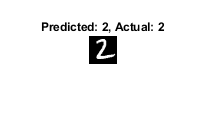

% load MNISTModel
% 
% % Predict the class of an image
% randIndx = randi(numel(labelsTest));
% img = imgDataTest(:,:,1,randIndx);
% actualLabel = labelsTest(randIndx);
% 
% predictedLabel = net.classify(img);
% imshow(img);
% title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])

## Need a starting point? Check the documentation!

Search "deep learning" in the documentation for more.

Here is a specific article that talks about the task we are doing here.

web(fullfile(docroot, 'nnet/deep-learning-training-from-scratch.html'))

## Prepare the CNN

We found an example of a convolutional neural network (CNN) in the documentation. One of the simplest possible convnets, it contains one convolutional layer, one ReLU, one pooling layer, and one fully connected layer. Let's utilize it as our first attempt at classifying these images.

% layers = [  imageInputLayer([28 28 1])
%             convolution2dLayer(5,20)
%             reluLayer
%             maxPooling2dLayer(2, 'Stride', 2)
%             fullyConnectedLayer(10)
%             softmaxLayer
%             classificationLayer()   ]

layers =   7x1 Layer array with layers:

     1   ''   Image Input             28x28x1 images with 'zerocenter' normalization
     2   ''   Convolution             20 5x5 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''   ReLU                    ReLU
     4   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Fully Connected         10 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex

## Attempt 1: Set training options and train the network

Let's use default values (except for miniBatchSize, which controls the memory of the computations) and try training this network.

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:01 |        8.50% |      14.1906 |          0.0100 |


|       1 |          50 |       00:00:15 |       10.80% |          NaN |          0.0100 |


|       1 |          53 |       00:00:16 |       10.60% |          NaN |          0.0100 |
|========================================================================================|


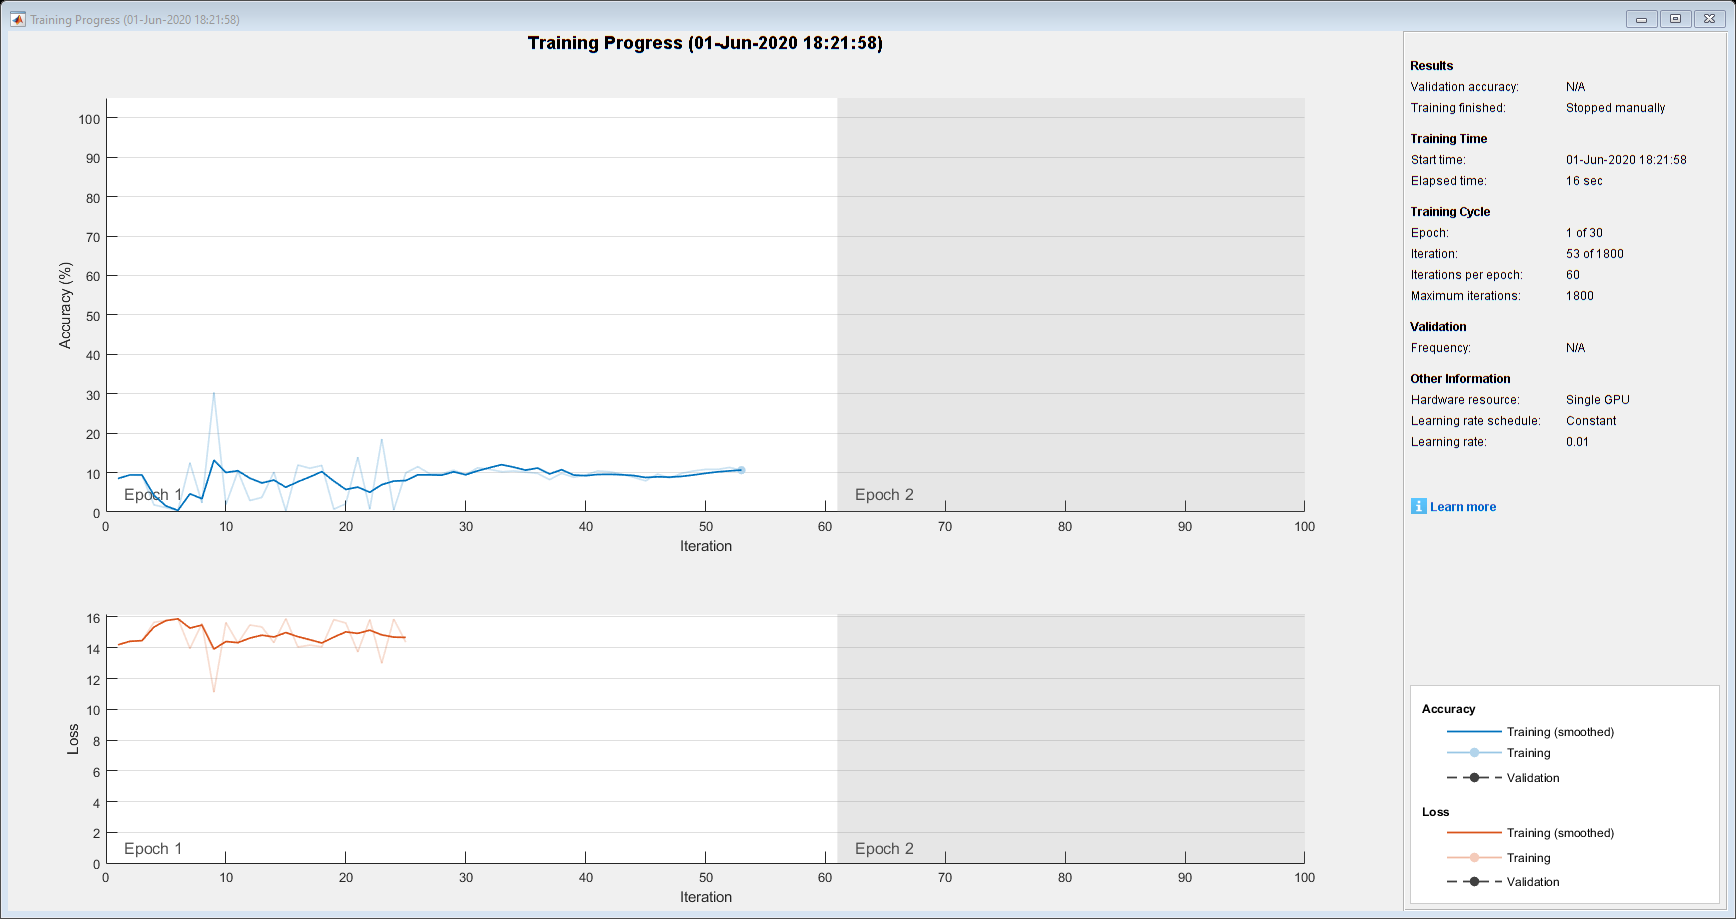

% miniBatchSize = 1000;
% options = trainingOptions( 'sgdm',...
%     'MiniBatchSize', miniBatchSize,...
%     'Plots', 'training-progress');
% 
% net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 2: Change the learning rate

That didn't work too well. Let's try changing one of the main parameters that affects neural network training: the **learning rate.**

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:00 |        7.90% |      13.9302 |      1.0000e-04 |


|       1 |          50 |       00:00:08 |       88.40% |       1.0725 |      1.0000e-04 |


|       2 |         100 |       00:00:16 |       90.30% |       0.6352 |      1.0000e-04 |


|       3 |         150 |       00:00:25 |       91.30% |       0.6120 |      1.0000e-04 |


|       4 |         200 |       00:00:33 |       92.40% |       0.5214 |      1.0000e-04 |


|       5 |         250 |       00:00:41 |       93.10% |       0.4856 |      1.0000e-04 |


|       5 |         255 |       00:00:42 |       92.20% |       0.4852 |      1.0000e-04 |
|========================================================================================|


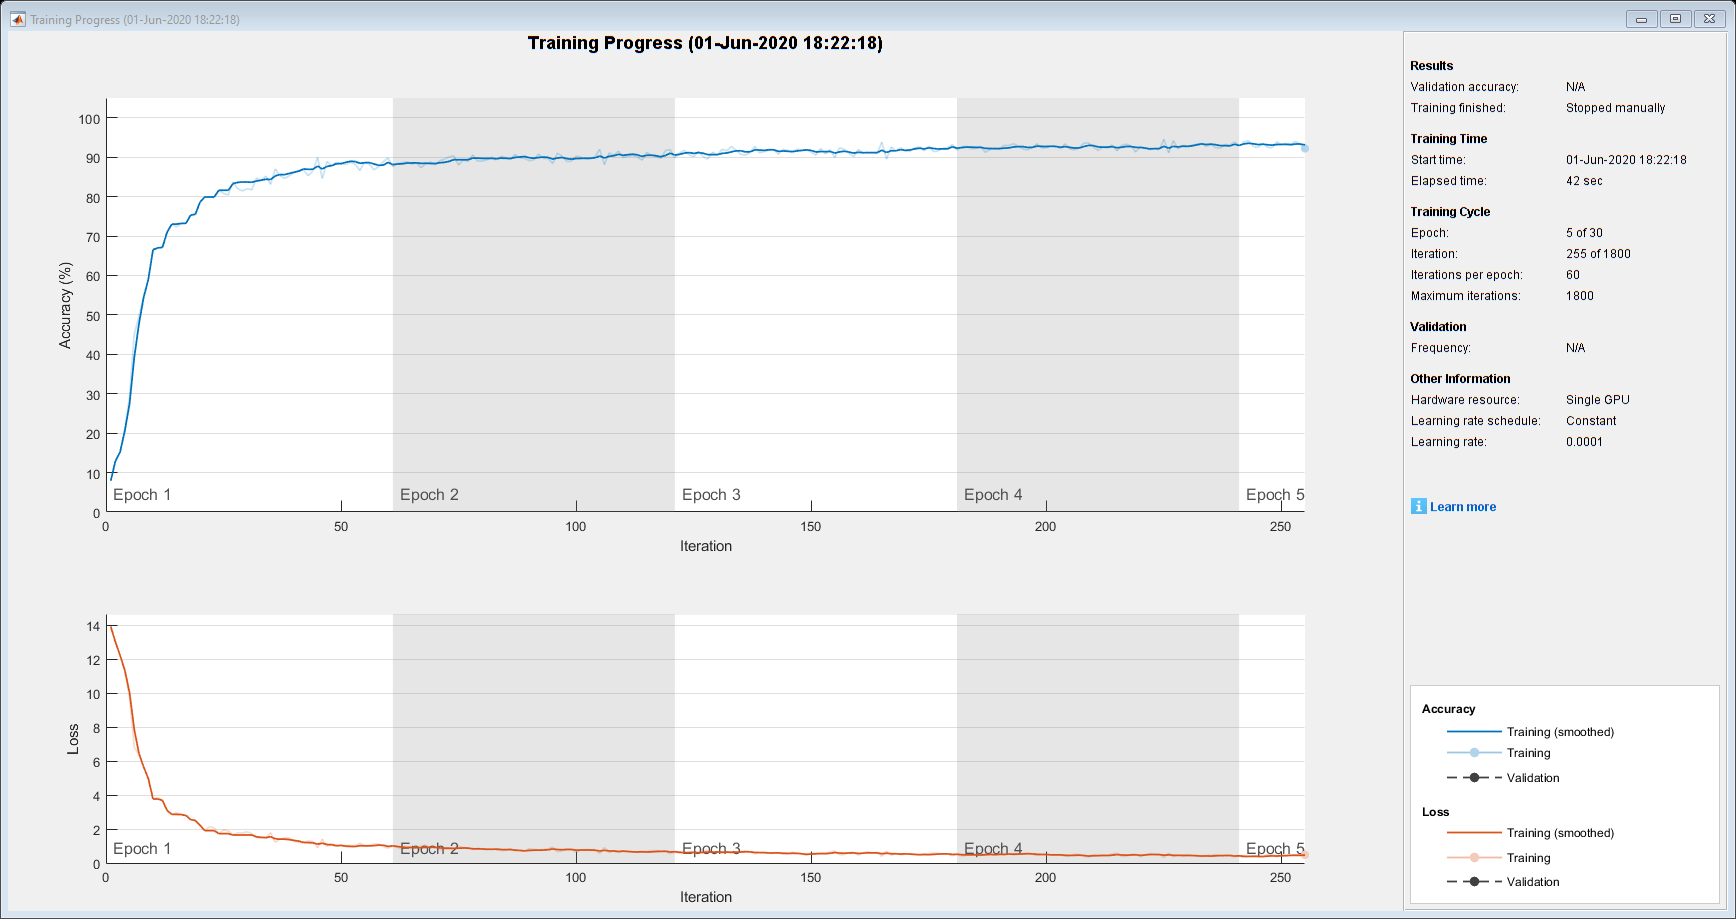

% options = trainingOptions( 'sgdm',...
%     'MiniBatchSize', miniBatchSize,...
%     'Plots', 'training-progress',...
%     'InitialLearnRate', 0.0001);
% 
% net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Attempt 3: Change the network architecture

Sometimes, it's not the learning rate that needs changing. Other factors about the model can affect the training as well. Here, instead of playing with hyperparameters such as the learning rate, we can use a more sophisticated CNN in the first place. This one has multiple convolution layers, as well as **batch normalization** layers, which improve the quality and convergence rate of the training.

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:01 |       12.50% |       2.8562 |          0.0100 |


|       1 |          50 |       00:00:36 |       95.90% |       0.1481 |          0.0100 |


|       2 |         100 |       00:01:19 |       98.20% |       0.0700 |          0.0100 |


|       3 |         150 |       00:01:37 |       97.70% |       0.0690 |          0.0100 |


|       4 |         200 |       00:01:54 |       98.00% |       0.0675 |          0.0100 |


|       5 |         250 |       00:02:11 |       97.50% |       0.0846 |          0.0100 |


|       5 |         300 |       00:02:27 |       98.80% |       0.0399 |          0.0100 |


|       6 |         350 |       00:02:44 |       98.80% |       0.0530 |          0.0100 |


|       7 |         400 |       00:03:01 |       99.20% |       0.0301 |          0.0100 |


|       8 |         450 |       00:03:18 |       99.10% |       0.0350 |          0.0100 |


|       9 |         500 |       00:03:34 |       98.50% |       0.0399 |          0.0100 |


|      10 |         550 |       00:03:53 |       98.50% |       0.0544 |          0.0100 |


|      10 |         600 |       00:04:12 |       99.50% |       0.0251 |          0.0100 |


|      11 |         650 |       00:04:31 |       99.00% |       0.0386 |          0.0100 |


|      12 |         700 |       00:04:49 |       99.60% |       0.0210 |          0.0100 |


|      13 |         750 |       00:05:08 |       99.60% |       0.0234 |          0.0100 |


|      14 |         800 |       00:05:26 |       99.00% |       0.0290 |          0.0100 |


|      15 |         850 |       00:05:49 |       99.00% |       0.0424 |          0.0100 |


|      15 |         900 |       00:06:13 |       99.70% |       0.0189 |          0.0100 |


|      16 |         946 |       00:06:32 |       99.30% |       0.0236 |          0.0100 |
|========================================================================================|


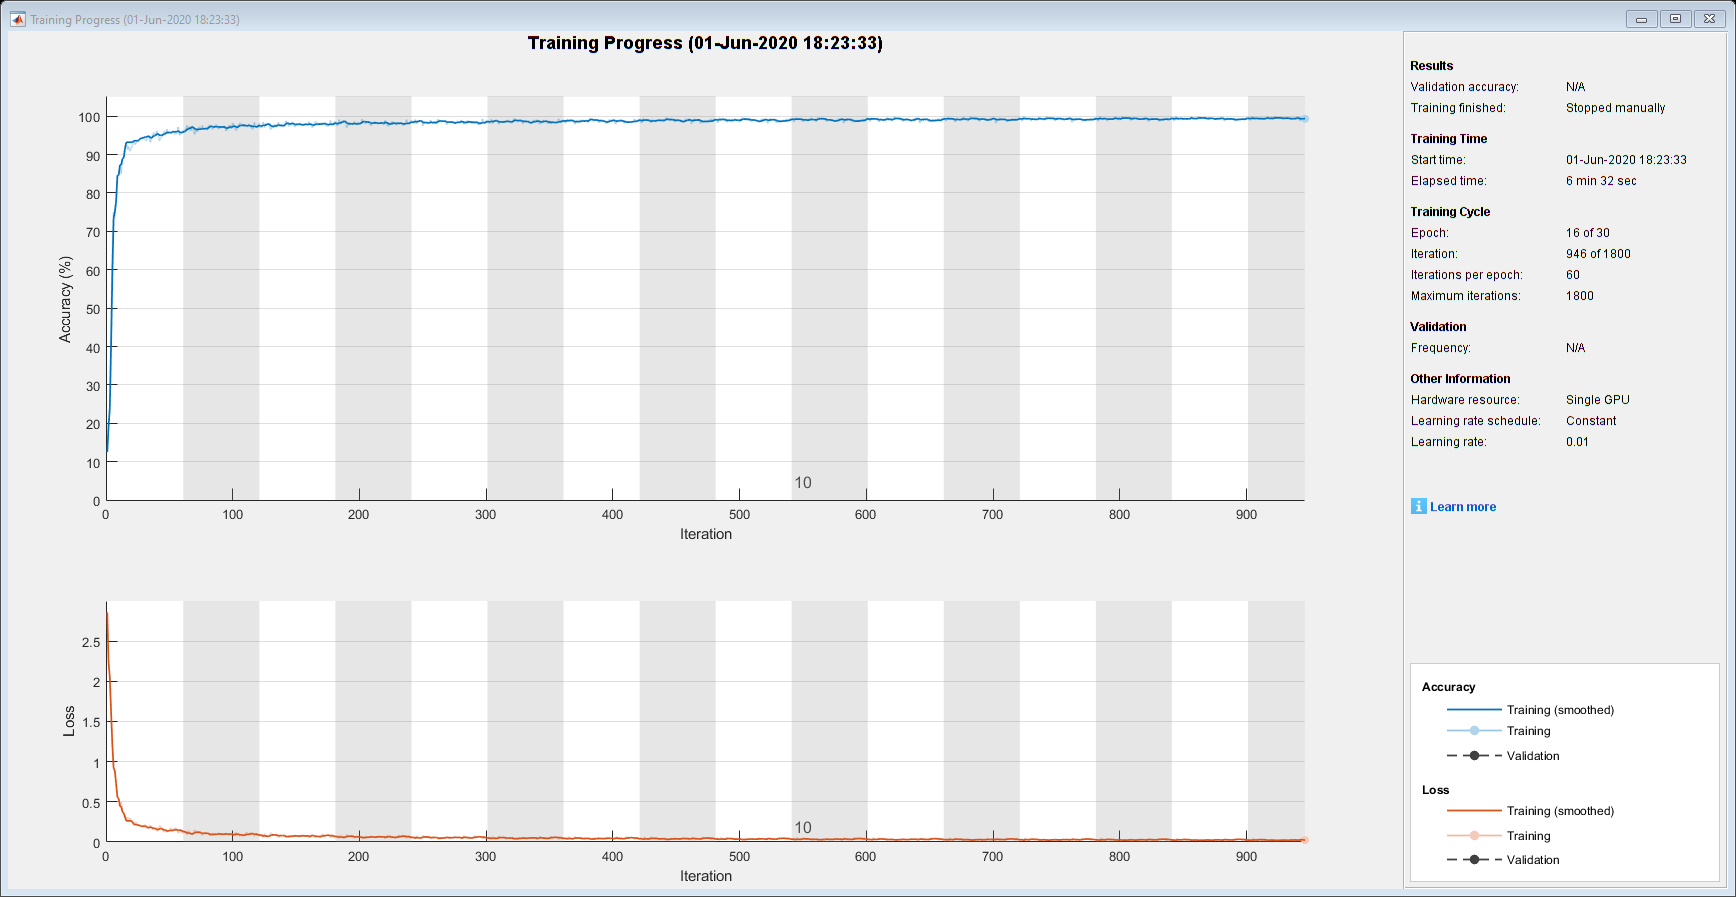

% layers = [
%     imageInputLayer([28 28 1])
% 
%     convolution2dLayer(3,16,'Padding',1)
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(3,32,'Padding',1)
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(3,64,'Padding',1)
%     batchNormalizationLayer
%     reluLayer
% 
%     fullyConnectedLayer(10)
%     softmaxLayer
%     classificationLayer];
% 
% options = trainingOptions( 'sgdm',...
%     'MiniBatchSize', miniBatchSize,...
%     'Plots', 'training-progress');
% 
% net = trainNetwork(imgDataTrain, labelsTrain, layers, options);

## Classify the test data set

We have a separate set of images in the MNIST dataset set aside specifically for testing. Let's use the test data to test the accuracy of the model we just trained.

% predLabelsTest = net.classify(imgDataTest);
% 
% testAccuracy = sum(predLabelsTest == labelsTest) / numel(labelsTest)

testAccuracy = 0.9901

## Try to classify something else

Of course, we will need to come up with models for other types of data when the classifier fails.

% clear

camera = webcam; % Connect to the camera
nnet = net;  % Load the neural net

% for frames = 1: 30   
    picture = camera.snapshot;       
    picture = rgb2gray(picture)% Take a picture    

picture = 480×640 uint8 matrix
    95    76    65    55    50    57    88    99    97   101    96    89    84    73    63    57    52    48    48    46    45    45    45    46    46    46    44    40    38    35    32    33    40    48    67    82    90    93    96    96    98   104   103   100    94    95    87    74    70    67
   102    83    71    60    58    73    89    89    92    97    97    90    81    69    59    54    49    49    48    47    47    47    48    48    48    46    45    41    40    39    36    39    47    64    81    93    98   102   107   110   114   112   108   104    98    95    85    75    72    70
   113    92    75    65    65    70    77    81    88    96    96    88    77    65    57    54    51    49    48    48    48    48    48    49    49    48    46    45    43    42    40    43    55    70    83    98   104   110   116   116   113   111   107   106   101    96    88    79    76    73
   122   102    83    71    66    67    71    74    81    86    86

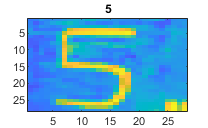

    picture = imresize(picture,[28,28]);  % Resize the picture

    label = classify(nnet, picture);        % Classify the picture
       
    image(picture);     % Show the picture
    title(char(label)); % Show the label

    drawnow;   
% end






















% img = imread('letterW.png');
% actualLabel = 'W';
% 
% predictedLabel = net.classify(img);
% imshow(img);
% title(['Predicted: ' char(predictedLabel) ', Actual: ' char(actualLabel)])


% clear
% % Connect to the first webcam
% cam = webcam(1);
% 
% %% Single Image
% 
% % % Take a single image from cam
% % img = snapshot(camera);
% % % Display image
% % imshow(img)       
% while true   
%     picture = cam.snapshot;              % Take a picture    
%     picture = imresize(picture,[28,28]);  % Resize the picture
% 
%     label = classify(net, picture);        % Classify the picture
%        
%     image(picture);     % Show the picture
%     title(char(label)); % Show the label
%     drawnow;   
% end

%% Video

% % Loop 30 times
% for frames = 1:30        
%     % Take single image from cam
%     img = snapshot(cam);  
%     % Display image
%     imshow(img)       
% % End loop
% end                         

%% Classification

% % Load the pretrained GoogLeNet network
% nnet = googlenet;        
% % Loop 250 times
% for n = 1:250            
%     % Take single image
%     img = snapshot(cam);     
%     % Resize image to 224x224 pixels
%     img = imresize(img, [224, 224]);
%     % Classify image
%     [label, score] = classify(nnet, img);
%     % Display image
%     imshow(img)
%     % Show label, score
%     title({char(label), num2str(max(score),2)});
% % End loop
% end 
